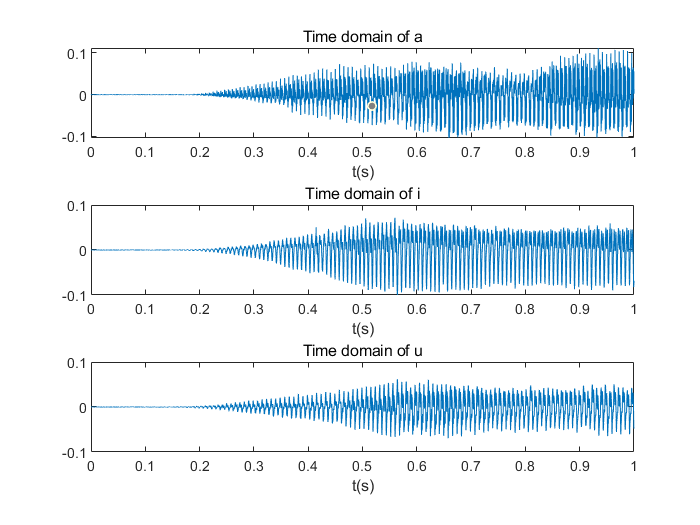

%sample with 16000Hz

% recorder=audiorecorder(16000,16,1);
% %记录/a/
% disp('start recording');
% recordblocking(recorder,1);
% disp('end recording');
% a=getaudiodata(recorder);
% filename='a.wav';
% audiowrite(filename,a,16000);
% 
% %记录/i/
% disp('start recording');
% recordblocking(recorder,1);
% disp('end recording');
% i=getaudiodata(recorder);
% filename='i.wav';
% audiowrite(filename,i,16000);
% 
% %记录/u/
% disp('start recording');
% recordblocking(recorder,1);
% disp('end recording');
% u=getaudiodata(recorder);
% filename='u.wav';
% audiowrite(filename,u,16000);

[a,fsa]=audioread('a.wav');
[i,fsi]=audioread('i.wav');
[u,fsu]=audioread('u.wav');

%plot waveform
figure
subplot(3,1,1);
ta=0:1/fsa:(length(a)-1)/fsa;
plot(ta,a);
xlabel('t(s)');
title('Time domain of a');
subplot(3,1,2);
ti=0:1/fsi:(length(i)-1)/fsi;
plot(ti,i);
xlabel('t(s)');
title('Time domain of i');
subplot(3,1,3);
tu=0:1/fsu:(length(u)-1)/fsu;
plot(tu,u);
xlabel('t(s)');
title('Time domain of u');
axis([0 1 -0.1 0.1]);

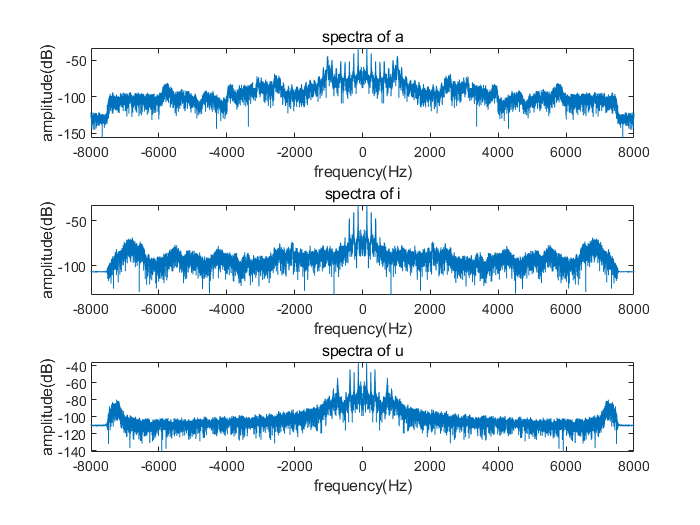


%plot spectra

figure
subplot(3,1,1);
a_f=fftshift(fft(a));
f_a=(-length(a_f)/2:length(a_f)/2-1)*fsa/length(a_f);
plot(f_a,mag2db(abs(a_f)*2/length(a_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of a');
subplot(3,1,1);
a_f=fftshift(fft(a));
f_a=(-length(a_f)/2:length(a_f)/2-1)*fsa/length(a_f);
plot(f_a,mag2db(abs(a_f)*2/length(a_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of a');
subplot(3,1,2);
i_f=fftshift(fft(i));
f_i=(-length(i_f)/2:length(i_f)/2-1)*fsi/length(i_f);
plot(f_i,mag2db(abs(i_f)*2/length(i_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of i');
subplot(3,1,3);
u_f=fftshift(fft(u));
f_u=(-length(u_f)/2:length(u_f)/2-1)*fsu/length(u_f);
plot(f_u,mag2db(abs(u_f)*2/length(u_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of u');

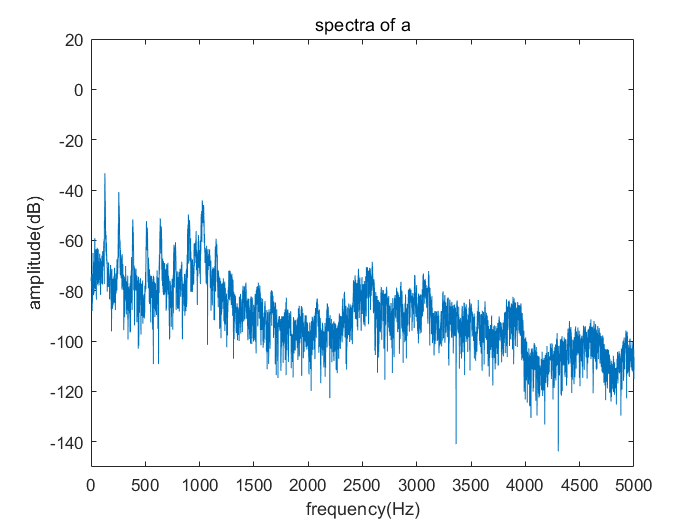


figure
plot(f_a,mag2db(abs(a_f)*2/length(a_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of a');
axis([0 5000 -150 20]);

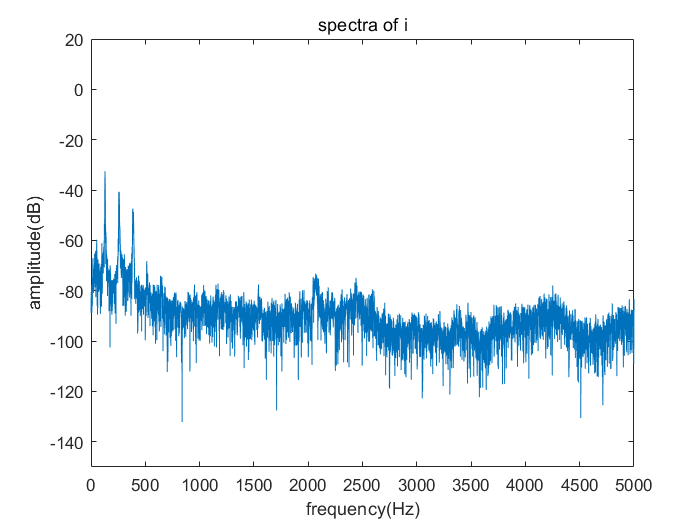

figure
plot(f_i,mag2db(abs(i_f)*2/length(i_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of i');
axis([0 5000 -150 20]);

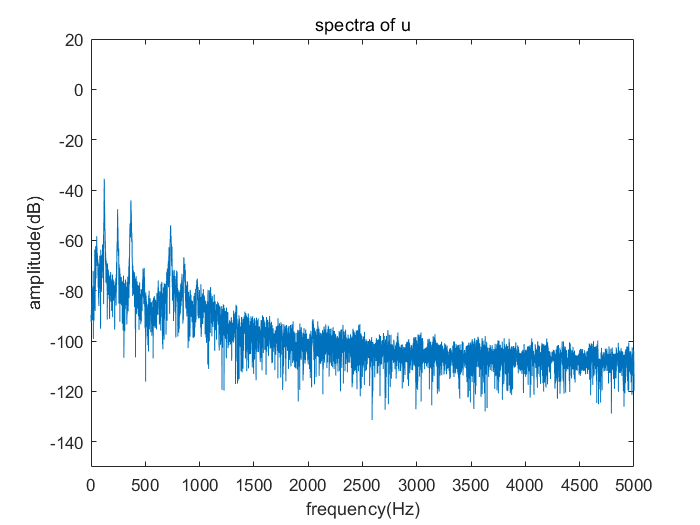

figure
plot(f_u,mag2db(abs(u_f)*2/length(u_f)));
xlabel('frequency(Hz)');
ylabel('amplitude(dB)');
title('spectra of u');
axis([0 5000 -150 20]);